# LAB4

Seyyed Mohammad Matin Alemohammad (810197457)

Amirhossein Mohammadi (810197689)

## 1. Bit generation

clc
clear
close all
N = 10; %pkt_size
M = 4; %4PAM
k = log2(M);
b_tx = bit_gen(N, k)

b_tx =      0     0
     1     1
     0     0
     0     1
     0     0
     0     1
     0     0
     0     1
     0     0
     1     0


## 2. Bit to Sym

b_gray = gray_code(k);
dec = bi2de(b_tx);
dec_gray = bi2de(b_gray);
sym_idx = zeros(N, 1);
for i=1:M
    sym_idx(dec == dec_gray(i))= i-1;
end
disp(sym_idx);

     0
     2
     0
     1
     0
     1
     0
     1
     0
     3



[cons, Es_avg] = constellation(M, "pam");
mod_sym = cons(sym_idx+1)

mod_sym =    -1.3416
    0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
   -0.4472
   -1.3416
    1.3416


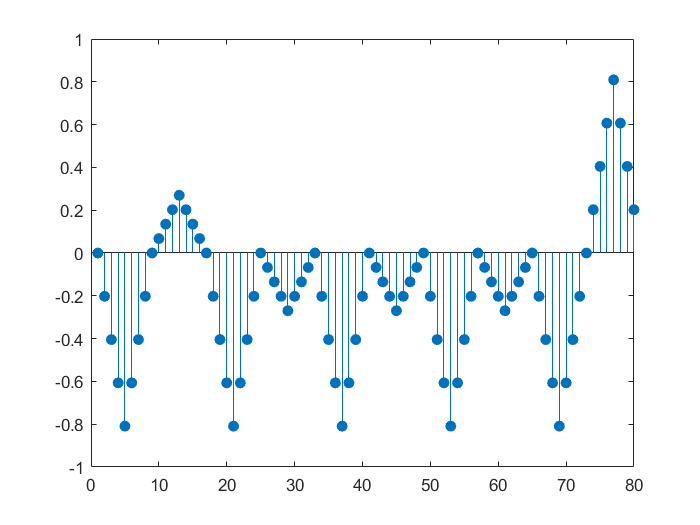

fs = 1;
smpl_per_symbl = 8;
[tx_out, ~] = pulse_modulation(sym_idx, "pam", M, fs, smpl_per_symbl, "triangular" , "conv");
stem(tx_out, "filled")

tx_out

tx_out =          0
   -0.2023
   -0.4045
   -0.6068
   -0.8090
   -0.6068
   -0.4045
   -0.2023
         0
    0.0674
